# Actividad_8.1 _SLAM_de_Lidar_parte2_complexMap

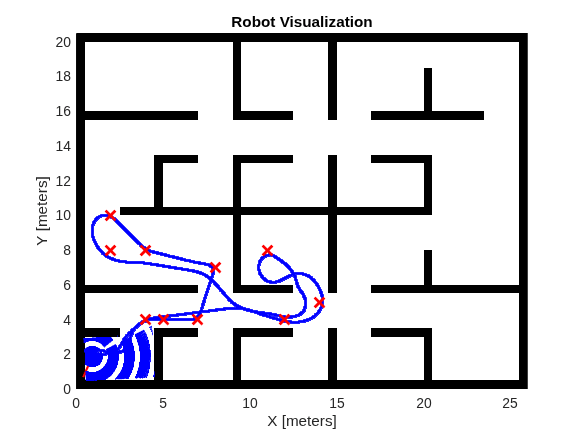


% Parámetros físicos del robot diferencial
rWheel = 0.05;                       % Radio de la rueda [m]
axleLength = 0.18;                   % Distancia entre ruedas [m]
ddRobot = DifferentialDrive(rWheel, axleLength);  % Modelo de robot diferencial

% Tiempo de muestreo y vector de tiempo de simulación
Ts = 0.05;                           % Tiempo de muestreo [s] (valor pequeño = más precisión)
timeVector = 0:Ts:83;              % Intervalo de tiempo largo para completar la trayectoria

% Estado inicial del robot [x; y; orientación]
initialPose = [1; 2; 0];         % Ubicación inicial (mirando hacia arriba)
robotPose = zeros(3, numel(timeVector)); 
robotPose(:,1) = initialPose;       % Asignar condición inicial al primer valor

% Cargar el mapa del entorno (evitar líneas negras)
close all
load complexMap                    % Mapa lógico con obstáculos (líneas negras)

% Configuración del sensor Lidar
lidar = LidarSensor;
lidar.sensorOffset = [0, 0];                     % Sensor en el centro del robot
lidar.scanAngles = linspace(-pi, pi, 360);       % Ángulos del escaneo (360 = buena cobertura)
lidar.maxRange = 5;                              % Distancia máxima de detección (ajustada)

% Visualizador del entorno y del robot
visual = Visualizer2D;
visual.hasWaypoints = true;
visual.mapName = 'map';                          % El nombre con el que Visualizer2D busca el mapa cargado
attachLidarSensor(visual, lidar);                % Vincula el sensor Lidar al visualizador

%% Path planning and following

% Definir los waypoints que el robot debe seguir
puntosRuta = [initialPose(1:2)'; % Inicia desde su posición inicial
              4,4;
              7,4;
              8,7;
              4, 8;
              2,10;
              2,8;
              12,4;
              11,8;
              14,5;
              5,4;
              1,2];

% Configuración del controlador Pure Pursuit
ppController = controllerPurePursuit;
ppController.Waypoints = puntosRuta;
ppController.LookaheadDistance = 0.5;            % Distancia de anticipación (más pequeña = mayor precisión)
ppController.DesiredLinearVelocity = 0.7;        % Velocidad lineal deseada (moderada para evitar errores)
ppController.MaxAngularVelocity = 20;            % Controla la agresividad de los giros

% Algoritmo de evasión de obstáculos - VFH (Vector Field Histogram)
vfhAlg = controllerVFH;
vfhAlg.DistanceLimits = [0.05, 3];               % Límites mínimo y máximo de distancia para detectar obstáculos
vfhAlg.NumAngularSectors = 900;                  % Mayor número = mejor resolución angular
vfhAlg.HistogramThresholds = [5, 10];            % Umbrales que determinan cuándo evitar un obstáculo
vfhAlg.RobotRadius = axleLength;                 % Radio del robot (usamos el largo del eje como aproximación)
vfhAlg.SafetyDistance = axleLength;              % Margen de seguridad frente a obstáculos
vfhAlg.MinTurningRadius = 0.1;                   % Radio mínimo para que el robot pueda girar

%% Bucle principal de simulación
controlRate = rateControl(1/Ts);                 % Controla la frecuencia del ciclo de simulación

for k = 2:numel(timeVector)
    
    % Obtener la posición actual y el escaneo del Lidar
    currentPose = robotPose(:, k-1);
    distances = lidar(currentPose);              % Rangos medidos desde la posición actual
    
    % Calcular velocidades deseadas (Pure Pursuit + VFH)
    [vLin, wAng, puntoAnticipado] = ppController(currentPose);  % Obtener velocidades y punto de seguimiento
    directionToTarget = atan2(puntoAnticipado(2) - currentPose(2), ...
                              puntoAnticipado(1) - currentPose(1)) - currentPose(3);
    newDirection = vfhAlg(distances, lidar.scanAngles, directionToTarget);
    
    % Si hay una dirección libre distinta, modificar el giro
    if ~isnan(newDirection) && abs(newDirection - directionToTarget) > 0.1
        wAng = 0.5 * newDirection;               % Redirecciona con ganancia suave
    end
    
    % Control del robot - transformar velocidades al sistema global
    velBody = [vLin; 0; wAng];                   % Velocidades en marco del cuerpo [vx; vy; w]
    velWorld = bodyToWorld(velBody, currentPose); % Transformación al sistema del mundo
    
    % Verificar si se llegó al destino
    goalPoint = puntosRuta(end,:);
    if norm(robotPose(1:2,k) - goalPoint') < 0.2
        break;                                   % Detener si está cerca del objetivo final
    end
    
    % Integración discreta hacia la siguiente pose
    robotPose(:,k) = currentPose + velWorld * Ts;
    
    % Actualizar visualización del entorno y robot
    visual(robotPose(:,k), puntosRuta, distances);
    waitfor(controlRate);
end